# WRITE POINTs

In this file, we present how to use the function *Func_WritePoints* to export a `.dat` file containing the 1P-BD of the model that must be imported in the main XPPAUT window. In this demo file, we export a `.dat` file associated with the 1P-BD of the Chay Keizer fast-subsystem computed by using `c` as the main bifurcation parameter. The fast subsystem Chay and Keizer model is the following.

$\begin{array}{l}
c_m \;\dot{\;v} =-\left(I_K +I_{\textrm{Ca}} +I_{K\left(\textrm{Ca}\right)} +I_{K\left(\textrm{ATP}\right)} \right),\\
\;\;\;\;\;\;\dot{n} =\left(n_{\infty \;} -n\right)\tau_n^{-1} \ldotp 
\end{array}$ (1)

For more details regarding (1), please refer to [1].

[1] Chay TR, Keizer J. *Minimal model for membrane oscillations in the pancreatic beta-cell*. Biophysic Journal, 1983.

## ENVIROMENT SET-UP

We set up the environment by cleaning the workspace and the command window of the current MATLAB session and by closing all the opened figures. Then, we proceed by importing the folders and subfolders where the main XPPLORE functions are stored.

% ENVIRONMENT
clear all; close all; clc;

% XPPLORE
addpath(genpath('../../Function_Visualization'))
addpath(genpath('../../Function_XPPAUT'))

## MODEL STRUCTURE

We use the function *Func_ReadModel *to read the model considered in this case.

% MODEL
M = Func_ReadModel('ck.ode');

## AUTORePO

We can load the continuation results through the function *Func_ReadAutoRepo*. As you can see in the following, the structure `AR` contains only a single 1P-BD with main bifurcation parameter `c`.

% AUTORePO - All
AR = Func_ReadAutoRepo(M,'ck.auto');

AR:
    Parsing settings ...completed!
    Parsing hot parameters ...completed!
    Parsing branches & labelled points ...completed!
    Parsing Special Solutions...completed!

    Summary:
        1P-BD - Name: BD1_c - Main: c


## VISUALIZATION

Before creating the `.dat` file, we visualize the 1P-BD.

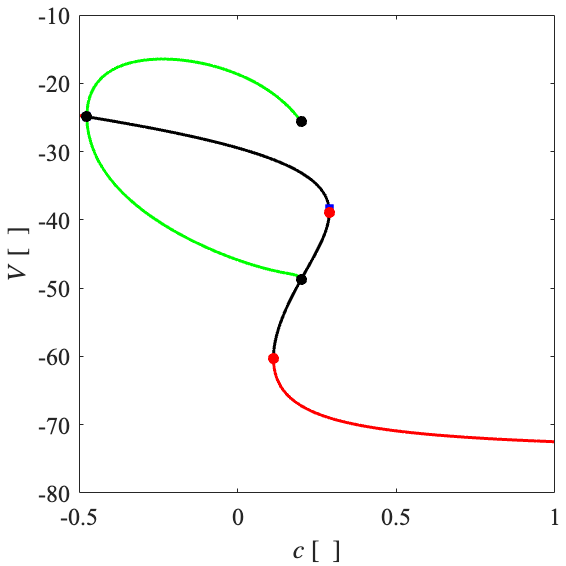

% VISUALIZATION
fig = figure();

Func_VisualizeDiagram(M,AR.BD1_c)
Func_VisualizeLabPoints(M,AR.BD1_c)

xlim([-0.5   1]), xlabel('$c$ [\ ]','interpreter','latex')
ylim([-80  -10]), ylabel('$V$ [\ ]','interpreter','latex')

Func_FigStyle(fig)

## WRITE POINTs

Now, we create the `.dat` file version of the previous BD. To do so, we use the function *Func_WritePoints. *This will produce an equivalent result of the *WritePoints* routine implemented in XPPAUT. Specifically, it exports a 1 or 2P-BD in a `.dat` file. This dataset can be imported in the main XPPAUT window by using (`G)raphic` s`tuff/(F)reeze/(B)if.Diag`. The *Func_WritePoints* function accepts as inputs:

- **M**: Model structure.

- **BD**: Bifurcation diagram structure.

- **fBD**: The name of the file where to export the data.

% EXPORT
Func_WritePoints(M,AR.BD1_c,'BD.dat')

## RESULTs

The following picture shows how the 1P-BD looks like after being exported through the function *Func_WritePoints *in the main XPPAUT window. Specifically, to generate this image you must open the file `ckT.ode` by using XPPAUT. Then, you should set up the main visualization window in order to visualize along the x/y axis the variable c/v. Then, you can load the previously exported `BD.dat` file by using the `Graphic` `stuff` command. Finally, by solving the dynamical system numerically, you can superimpose its solution over the previously set-up plane.